Part 2-1 A

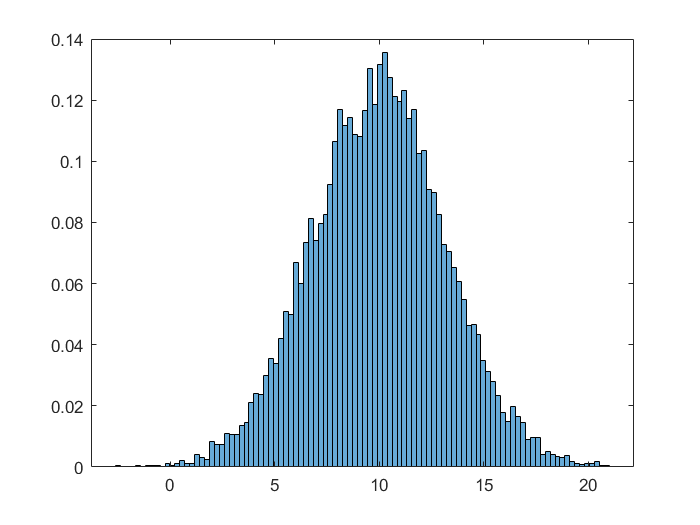

rng(1)
normal_samples = normrnd(10, sqrt(10),[1, 10000]);
histogram(normal_samples,100,'Normalization', 'pdf');

Part 2-1 B

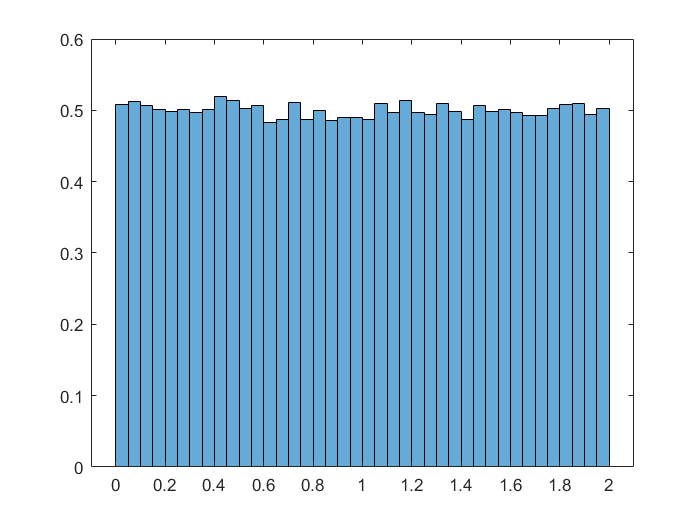

rng(1)
uniform_samples = 2*rand([1,100000]);
histogram(uniform_samples, 'Normalization','pdf')

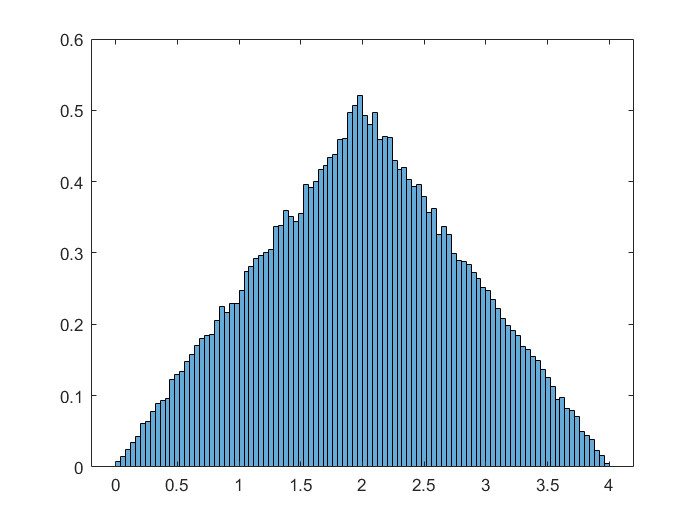

x_n_1 = zeros(1,100001);
x_n = zeros(1,100001);
x_n_1(1:100000) = uniform_samples(:);
x_n(2:100001) = uniform_samples(:);
summation = x_n + x_n_1;
histogram(summation,100, 'Normalization', 'pdf')

Since two uniform random variable are adding up and summation of two uniform random variable is like a convolution of two rectangular pulses the result is a traianfular puls.

Part 2-1 C

Histogram looks like a normal distribution PDF. since summation of uniform random varable tends to normal, here adding up for uniform random variable creates a normal density PDF.

summation = zeros(1, 100000)

summation =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


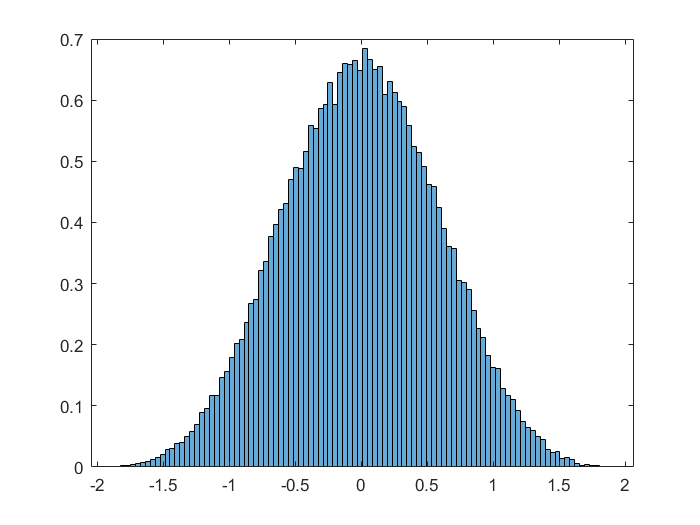

for i =1:4
    uniform_samples = rand([1,100000]) - 0.5;
    summation = summation + uniform_samples;
end
histogram(summation,100, 'Normalization', 'pdf')

Part 2-2 1.A

Here Manual filter has been implemented, as we can see the result is the same as 'filter' command.

x = zeros(1, 100)

x =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x(1) = 1

x =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y = zeros(1, 100)

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y(1) = 1

y =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


y(2) = 2.5

y =     1.0000    2.5000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


y(3) = 1

y =     1.0000    2.5000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


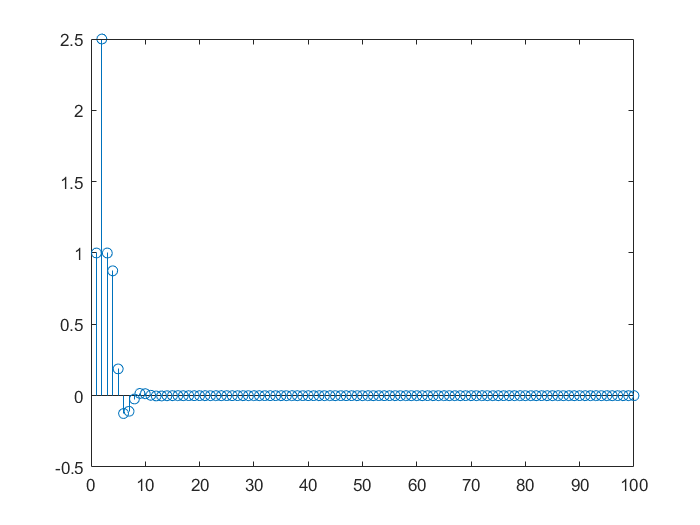

for i = 4:100
    y(i) = x(i) + 2*x(i-1) + x(i - 3) + 0.5* y(i-1) - 0.25*y(i-2); 
end
stem(1:100, y)

a = [1, -0.5, 0.25]

a =     1.0000   -0.5000    0.2500


b = [1, 2, 1]

b =      1     2     1


y = filter(b, a, x)

y =     1.0000    2.5000    2.0000    0.3750   -0.3125   -0.2500   -0.0469    0.0391    0.0312    0.0059   -0.0049   -0.0039   -0.0007    0.0006    0.0005    0.0001   -0.0001   -0.0001   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000


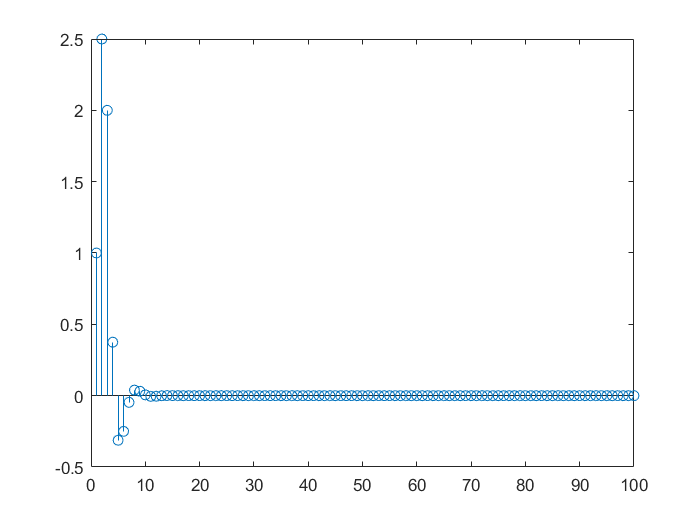

stem(1:100, y)

Part 2-2 2

close all
recived_signal = load('PacketsAndHeader.mat')

recived_signal = struct with fields:
    hdr_smpl: [864×1 double]
     rx_smpl: [32100×1 double]


header_sample = recived_signal.hdr_smpl;
rx_sample = recived_signal.rx_smpl;
len_header = length(header_sample);
len_recivedsignal = length(rx_sample);
fs = 10*10^6;
Ts = 1/fs;
time_header = (1:len_header)./len_header*Ts;
plot(time_header, real(header_sample))
hold on
plot(time_header,imag(header_sample))
time_recived = (1:len_recivedsignal)./len_recivedsignal*Ts

time_recived = 	1.0e+-7 *

    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011    0.0012    0.0012    0.0012    0.0012    0.0013    0.0013    0.0013    0.0014    0.0014    0.0014    0.0015    0.0015    0.0015    0.0016


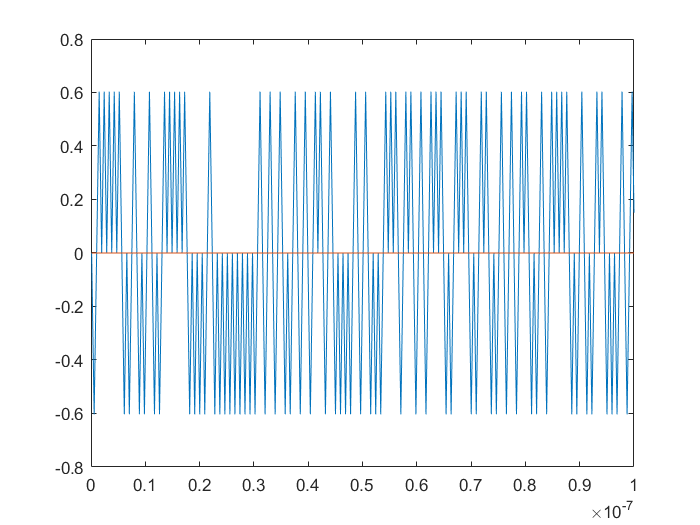

hold off

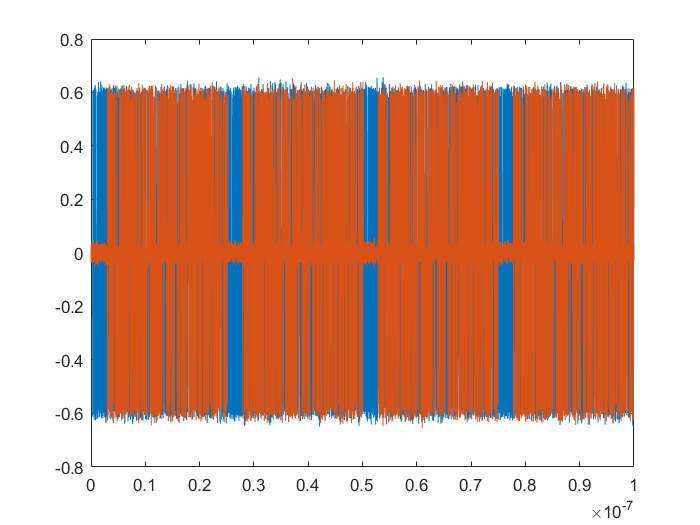

plot(time_recived, real(rx_sample))
hold on
plot(time_recived,imag(rx_sample))
hold off


%corr_header = xcorr(header_sample, header_sample)
%rx_header = xcorr(rx_sample, rx_sample);
rec_corr = corr_m(header_sample, rx_sample)

rec_corr = 	1.0e+02 *

  -0.0136 - 0.0004i   0.0071 - 0.0011i   0.0239 - 0.0016i   0.0356 - 0.0028i   0.0406 - 0.0033i   0.0386 - 0.0029i   0.0284 - 0.0033i   0.0113 - 0.0029i  -0.0110 - 0.0026i  -0.0379 - 0.0022i  -0.0631 - 0.0020i  -0.0815 - 0.0014i  -0.0890 - 0.0012i  -0.0805 - 0.0013i  -0.0624 - 0.0004i  -0.0410 - 0.0004i  -0.0220 - 0.0005i  -0.0126 - 0.0003i  -0.0107 - 0.0005i  -0.0131 - 0.0007i  -0.0166 - 0.0001i  -0.0178 - 0.0001i  -0.0139 - 0.0006i  -0.0071 - 0.0005i   0.0007 - 0.0011i   0.0105 - 0.0006i   0.0180 + 0.0001i   0.0235 - 0.0002i   0.0268 + 0.0001i   0.0251 - 0.0009i   0.0207 - 0.0019i   0.0150 - 0.0016i   0.0103 - 0.0019i   0.0097 - 0.0009i   0.0117 - 0.0002i   0.0153 + 0.0008i   0.0179 + 0.0024i   0.0173 + 0.0031i   0.0170 + 0.0042i   0.0197 + 0.0034i   0.0282 + 0.0024i   0.0465 + 0.0008i   0.0671 - 0.0005i   0.0837 - 0.0000i   0.0907 + 0.0003i   0.0811 + 0.0020i   0.0602 + 0.0031i   0.0318 + 0.0032i   0.0005 + 0.0038i  -0.0303 + 0.0036i


len_corr = abs(len_recivedsignal-len_header)+1

len_corr = 31237

time_corr = (1:len_corr).*Ts*1000

time_corr =     0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049    0.0050


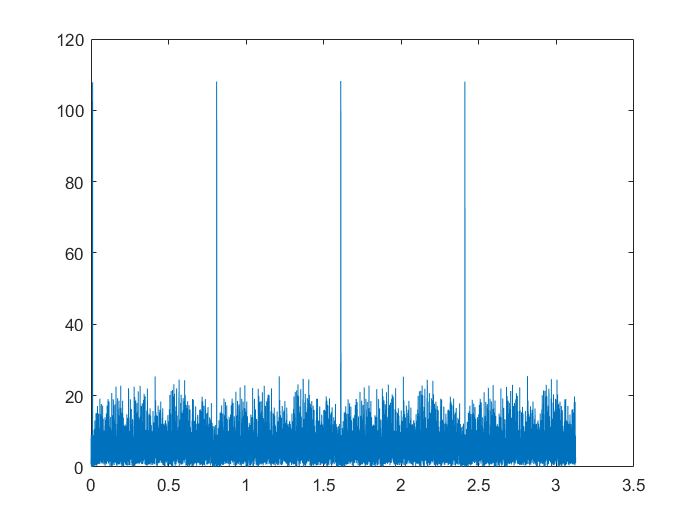

plot(time_corr, abs(rec_corr))

first peak is @(X = 0.0101) so the packet time is 0.8ms

R = ct = 3*10^8 * 0.0101*10^-3

R  = 3*10^8 * 0.0101*10^-3

R = 3030

The delaye between to symbols are 0.8ms

num symbol =1/ (0.8 /8) *1000 = 1000